% cut and align the neural activity based on task event written by NY

clear all;
close all;
clc;


Animal = 'tph314'; %'tph199';'tph209'
Date = '20240414'; % '20230602';'20230827'
totalTrial = 150;
Key = 'roving'; %'heavy90';'roving25s'
cellset_num = 3; %5; % num of session in all sessions % start from 0
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
layer_bounds_um = [168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
%     Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 1; %0: do not use, 1:use
% Define the folder where the CSV files are located
pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/tph314_roving/20240414_tph314/output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
image_reverse = 2; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
data_folder = ['/media/naohiro/SSD-SCTU3A/Nao_behavior/202403'  filesep Date '_' Animal '_' Key]; % from 24/6
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux %/202308
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/240605/'];

% plot event triggered neural activity
force_thr = 50; 
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 4:z scored by compared trials

load([data_folder filesep Animal '_behavior_' Date '_' Key '.mat']);

% neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
if contains(Key,'roving')
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
elseif contains(Key,'switching')
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_switching-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_switching_0.5.csv']);    
else
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
end
% all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
%%% have to return the line below %%%
global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
% acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

% %%% Temporal use
% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% % acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% % acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);
% acc_neural_activity_data = neural_activity_data; % temporal use
% acc_neural_property_data = neural_property_data; % temporal use

% sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))
% strcmp(neural_property_table(:,'Status'),'accepted')

% save table as mat file
save([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');

acc_neural_activity_data

acc_neural_activity_data =    21.8092   22.2124   -0.9918    3.0205    5.2833   18.4342    1.2251    2.6471    6.9614   10.7325   -0.8096   24.6864   11.0003   14.4152   32.2803    2.8423    0.4162    5.4392    1.8378   11.4760    2.3083   19.1324   10.5791    0.2620   32.4434    3.4661    5.6413   11.8139   -0.0499   25.0810   16.8110   -2.2887   -2.1485    1.5197   11.8757    2.0147   -2.9349    4.8235    4.8984   12.5761    1.2740    2.3841   20.9599   14.1068   10.2343   17.6328    5.3021    0.4348   16.9431    1.0532
   23.2145   25.0122   -2.6158    2.2206    5.6803   18.3148    3.2525    4.4373    3.8520    8.4883   -0.9018   23.2111   10.7266   15.5503   30.8093    4.6530    2.3150    4.6458    2.9613   12.8516    0.9299   25.4425    7.4270    0.5382   31.3936    2.8993    6.2243   12.7317   -2.2728   25.3593   15.1292   -3.3941   -2.8003    1.9152   11.6757    4.8576   -1.5731    5.6664    4.1081   11.0468    3.4974    3.2932   22.4603   15.4373    6.9343   20.9519    3.8570  

acc_neural_property_data

acc_neural_property_data =   255.0000  255.0000  255.0000   59.0000   28.0000    1.0000   10.1980    1.0000
  255.0000  255.0000  255.0000   58.0000    6.0000    1.0000   10.7703    1.0000
  255.0000  255.0000  255.0000   56.0000   16.0000    1.0000   10.8167    1.0000
  255.0000  255.0000  255.0000   50.0000   15.0000    1.0000   11.6619    1.0000
  255.0000  255.0000  255.0000  128.0000   20.0000    1.0000    9.0554    1.0000
  255.0000  255.0000  255.0000   96.0000   13.0000    1.0000    8.2462    1.0000
  255.0000  255.0000  255.0000   78.0000    7.0000    1.0000    9.8489    1.0000
  255.0000  255.0000  255.0000  102.0000    7.0000    1.0000    9.2195    1.0000
  255.0000  255.0000  255.0000  116.0000   11.0000    1.0000   11.0454    1.0000
  255.0000  255.0000  255.0000   75.0000   15.0000    1.0000    9.4868    1.0000


if Kota_alignment == 1    
    % Get a list of all CSV files in the folder
    csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
    
    % Initialize an empty cell array to store the matrices
    AlinmentTimingCells = {};
    
    % Loop through each CSV file and read the data
    for k = 1:length(csvFiles)
        % Get the full file name and read the CSV file
        fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
        data = table2array(readtable(fileName));
        
        % Store the data in the cell array
        AlinmentTimingCells{k} = data;
    end
end

% plot neural activity
% addpath([working_directory 'PCA_and_ICA\Subaxis']);
ylimit=[0 50];
mean_acc_neural_activity = mean(acc_neural_activity_data,2);
figure
% for i = 1:size(acc_neural_activity_data,2)
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    for j = 1:size(acc_neural_activity_data,2)
        hold on 
        r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
        hold off
    end
    alpha(r,0.1);

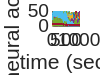

    hold on
    b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    ylabel('neural activity');
    xlabel('time (sec)')


% end
% saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

% plot neural activity heatmap
climit = [0 50]

climit =      0    50


figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = transpose(acc_neural_activity_data)

image =    21.8092   23.2145   22.1190   22.0802   19.5605   16.3138   15.3159   12.6924   14.6209   12.1100   10.2625    9.2859   12.0909   14.4480   17.1436   15.3774   15.2941   13.4570   12.9971   12.2713    8.0813    9.3622    7.3539    7.0766    7.5430    7.9500    5.9018    5.8587    6.5252    6.2986    4.2139    2.8871    2.9891    3.3117    3.5906    3.2437    1.7721    1.9786    1.1832    0.8493    1.7115    1.2972    2.4261    2.2250    2.6884    2.3692    3.2224    3.1211    3.0347    2.2784
   22.2124   25.0122   22.9286   21.8366   21.8349   20.1584   21.5806   21.3999   21.2707   23.1485   23.1264   19.5735   18.9128   16.8659   20.0310   18.8777   21.0908   18.1422   17.9673   16.4212   14.8761   14.5920   15.0731   15.9313   14.4443   12.6144   13.1221   13.6082   16.8686   17.8079   14.5184   16.7333   15.9460   16.7658   15.1483   14.5550   15.1820   14.8619   14.0060   13.4733   10.7768   11.1646   10.8854    8.6502    9.7806    8.4206    8.9685    9.9513   10.3251 

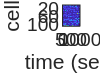

%     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(0:0.1:(size(acc_neural_activity_data,1)-1)/10,1:size(acc_neural_activity_data,2),image,clims);
%     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
% end

filename = [output_dir Date '_' Animal, '_all_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

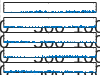

addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 10; %113;
ylimit=[0 150];
figure
for i = 1:example_num
    subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    xlim([0 (size(acc_neural_activity_data,1)-1)/10])
%     ylabel('neural activity');
%     xlabel('time (sec)')
end
filename = [output_dir Date '_'  Animal, '_exmple_activity_traces.png'];
saveas(gcf,filename);

0:0.1:(size(acc_neural_activity_data,2)-1)/10

ans =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


% plot example neural activity with behaviors
addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 10; %113;
ylimit=[0 150]

ylimit =      0   150


range_max =1000;
figure
for i = 1:example_num
    subaxis(example_num+3,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    b = plot(0:0.1:(range_max-1)/10,acc_neural_activity_data(1:range_max,display_start+i));
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 
    xlim([0 (range_max-1)/10])
%     ylabel('neural activity');
%     xlabel('time (sec)')
end

for i = 1:3
    subaxis(example_num+3,1,i+example_num, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
    normalized_behavior = normalize_rows(transpose(behavior_neural_time(1:range_max,5+i)))
    b = plot(0:0.1:(range_max-1)/10,normalized_behavior);
%     title([brain_roi_name(i)], 'FontSize',6);
    ylim([-0.2 1.2]); 
    xlim([0 (range_max-1)/10]);
%     ylabel('neural activity');
%     xlabel('time (sec)')
end

normalized_behavior =     0.8413    0.8127    0.8095    0.8095    0.8095    0.8074    0.8095    0.8105    0.8095    0.8105    0.8086    0.8095    0.8105    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8104    0.8095    0.8095    0.8095    0.8234    0.9887    1.0000    0.7810    0.0265         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0635    0.3968


normalized_behavior =     0.5012    0.5012    0.6232    0.6506    0.4665    0.3852    0.4805    0.4933    0.5016    0.5063    0.5054    0.4847    0.4511    0.4713    0.5446    0.5269    0.5057    0.4771    0.4345    0.4548    0.2767    0.5754    0.9771    0.4060    0.4116    0.4695    0.7835    0.5161    0.5535    0.6004    0.4727    0.3013    0.2219    0.2318    0.2259    0.2841    0.2921    0.2670    0.2875    0.2856    0.2898    0.3043    0.3900    0.3712    0.4327    0.5004    0.4253    0.4494    0.4639    0.4351


normalized_behavior =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     1     1     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


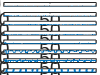

filename = [output_dir Date '_'  Animal, '_exmple_activity_behavior_traces.png'];
saveas(gcf,filename);

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
if categorize == 'depth'
    if image_reverse == 0
        depth = 1050 - acc_neural_property_data(:,4)*1050/(1280/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    elseif image_reverse == 2
        depth = 1050 - acc_neural_property_data(:,4)*1050/(1280/4); 
    else
        depth = acc_neural_property_data(:,4)*1050/(1280/4);
%     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    end
end

% determine which layer each cell belong by cell position
if categorize == 'layer'
%     layer_bounds_um = [140;250;260]; %[left, center,right] of the
%     Inscopix imaging FOV
    layer_bounds_pix = layer_bounds_um * (1280/4) /1050; 
    layer_bounds_len = length(layer_bounds_pix);
    x_pix = linspace(1, 200, layer_bounds_len);
    % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
    % TODO: have to be reverse y axis and x axis depending on the orientation of
    % the image
    if image_reverse == 0
        neural_locations = [acc_neural_property_data(:,5), acc_neural_property_data(:,4)];
    elseif image_reverse == 2
        neural_locations = [800/4 - acc_neural_property_data(:,5), 1280/4 - acc_neural_property_data(:,4)];        
    else
        % % reverse layer_bounds_pix
        % layer_bounds_pix = flip(layer_bounds_pix);
        neural_locations = [800/4 - acc_neural_property_data(:,5), acc_neural_property_data(:,4)];       
    end
    %reshape neural_locations to N*2
    % combine x_pix and layer_bounds_pix to 3*2
    linePoints = [x_pix(:), layer_bounds_pix(:)];
    % determine the layer each cell belong based on the matlab function
    % 0: layer2/3, 1: layer5
    pointAreas = classifyPoints(neural_locations, linePoints);
    % save table as mat file
    save([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'], 'pointAreas', '-append');
end

layer_bounds_pix =    51.2000  113.6762  127.3905  133.1810  137.4476


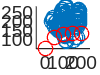

if categorize == 'layer'
    layer_bounds_pix
    close all
    figure;
    scatter(neural_locations(:,1),neural_locations(:,2));
    hold on;
    scatter(linePoints(:,1),linePoints(:,2),[],"red");
    axis equal;
    % plot().show
end

% 'behavior_neural_time'
trial_start = behavior_neural_time(:,3);
trial_end   = behavior_neural_time(:,4);
position    = behavior_neural_time(:,6);
force       = behavior_neural_time(:,7);
reward      = behavior_neural_time(:,8);
% find index of each event
trial_start_idx = find(trial_start == 1);
trial_end_idx   = find(trial_end == 1);
force_idx       = find(force > force_thr);
reward_idx      = find(reward == 1); 
position_diff   = diff(position);
position_idx    = find(position_diff > position_thr);
% idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
% event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
trial_start_act = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
trial_end_act   = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
position_act    = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
force_act       = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
reward_act      = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
sig_cell_idxs   = cell(0,5);

% only count first idx in 1 second
temp_position_idx = position_idx(1);
for i = 2:length(position_idx)
    if position_idx(i) - temp_position_idx(end) >= fps
        temp_position_idx(end+1) = position_idx(i);
    end
end
position_idx = temp_position_idx;

temp_force_idx = force_idx(1);
for i = 2:length(force_idx)
    if force_idx(i) - temp_force_idx(end) >= fps
        temp_force_idx(end+1) = force_idx(i);
    end
end
force_idx = temp_force_idx;

temp_reward_idx = reward_idx(1);
for i = 2:length(reward_idx)
    if reward_idx(i) - temp_reward_idx(end) >= fps
        temp_reward_idx(end+1) = reward_idx(i);
    end
end
reward_idx = temp_reward_idx;

% for i = 1:size(idxs,2)
%     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
exception_count = 0;
trial_start_acts = {};
for j = 1:length(trial_start_idx)
    if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        trial_start_act = trial_start_act+transpose(acc_neural_activity_data(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
        trial_start_acts{end+1}= transpose(acc_neural_activity_data(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:));
    end
end
trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
trial_start_acts = reshape(cell2mat(trial_start_acts),[size(acc_neural_activity_data, 2) size(trial_start_act,2) length(trial_start_idx)-exception_count]); %[191 31 147]);
if norm == 1
    trial_start_act = normalize_rows(trial_start_act);
elseif norm ==2 || norm ==4
       trial_start_act = zscore_rows(trial_start_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(trial_start_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_trial_start_acts = trial_start_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(trial_start_acts(i_cell,:)),squeeze(max_trial_start_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{1} = sig_cell_idx;
    end
    trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
end
[M,start_I] = max(trial_start_act,[],2);
trial_start_act = cat(2,start_I,trial_start_act);
trial_start_act = sortrows(trial_start_act);
trial_start_act_max_act_times = trial_start_act(:,1)/10 -2;
trial_start_act(:,1) = [];

exception_count = 0;
trial_end_acts = {};
for j = 1:length(trial_end_idx)
    if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        trial_end_act = trial_end_act+transpose(acc_neural_activity_data(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
        trial_end_acts{end+1}= transpose(acc_neural_activity_data(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:));
    end
end
trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
trial_end_acts = reshape(cell2mat(trial_end_acts),[size(acc_neural_activity_data, 2) size(trial_end_act,2) length(trial_end_idx)-exception_count]);
if norm == 1
    trial_end_act = normalize_rows(trial_end_act);
elseif norm ==2 || norm == 4
   trial_end_act = zscore_rows(trial_end_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(trial_end_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_trial_end_acts = trial_end_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(trial_end_acts(i_cell,:)),squeeze(max_trial_end_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{2} = sig_cell_idx;
    end
    trial_end_act = zscore_rows(trial_end_act(find(sig_cell_idx==1),:));
end
[M,end_I] = max(trial_end_act,[],2);
trial_end_act = cat(2,end_I,trial_end_act);
trial_end_act = sortrows(trial_end_act);
trial_end_act_max_act_times = trial_end_act(:,1)/10 -2;
trial_end_act(:,1) = [];

exception_count = 0;
position_acts = {};
for j = 1:length(position_idx)
    if position_idx(j)-fps*before_event<=0 | position_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        position_act = position_act+transpose(acc_neural_activity_data(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:)); 
        position_acts{end+1}= transpose(acc_neural_activity_data(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:));
    end
end
position_act = position_act/(length(force_idx)-exception_count);
position_acts = reshape(cell2mat(position_acts),[size(acc_neural_activity_data, 2) size(position_act,2) length(position_idx)-exception_count]);
if norm == 1
    position_act = normalize_rows(position_act);
elseif norm ==2 || norm == 4
       position_act = zscore_rows(position_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(position_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_position_acts = position_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(position_acts(i_cell,:)),squeeze(max_position_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{3} = sig_cell_idx;
    end
    position_act = zscore_rows(position_act(find(sig_cell_idx==1),:));
end
[M,pos_I] = max(position_act,[],2);
position_act = cat(2,pos_I,position_act);
position_act = sortrows(position_act);
position_act_max_act_times = position_act(:,1)/10 -2;
position_act(:,1) = [];

exception_count = 0;
force_acts = {};
for j = 1:length(force_idx)
    if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        force_act = force_act+transpose(acc_neural_activity_data(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
        force_acts{end+1}= transpose(acc_neural_activity_data(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:));
    end
end
force_act = force_act/(length(force_idx)-exception_count);
force_acts = reshape(cell2mat(force_acts),[size(acc_neural_activity_data, 2) size(force_act,2) length(force_idx)-exception_count]); %-1]);
if norm == 1
    force_act = normalize_rows(force_act);
elseif norm ==2 || norm ==4
       force_act = zscore_rows(force_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(force_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_force_acts = force_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal'); %temporal,'Alpha',0.001
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{4} = sig_cell_idx;
    end
    force_act = zscore_rows(force_act(find(sig_cell_idx==1),:));
end
[M,force_I] = max(force_act,[],2);
force_act = cat(2,force_I,force_act);
force_act = sortrows(force_act);
force_act_max_act_times = force_act(:,1)/10 -2;
force_act(:,1) = [];

exception_count = 0;
reward_acts = {};
for j = 1:length(reward_idx)
    if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
        exception_count = exception_count + 1;
    else
        reward_act = reward_act+transpose(acc_neural_activity_data(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
        reward_acts{end+1}= transpose(acc_neural_activity_data(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:));
    end
end
reward_act = reward_act/(length(reward_idx)-exception_count);
reward_acts = reshape(cell2mat(reward_acts),[size(acc_neural_activity_data, 2) size(reward_act,2) length(reward_idx)-exception_count]);
if norm == 1
    reward_act = normalize_rows(reward_act);
elseif norm ==2 || norm == 4
   reward_act = zscore_rows(reward_act); 
elseif norm ==3
    sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
    for i_cell = 1:size(acc_neural_activity_data, 2)
        [~,max_idx] = max(mean(reward_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
        max_reward_acts = reward_acts(i_cell,max_idx,:);
        [h,p] = ttest2(squeeze(reward_acts(i_cell,:)),squeeze(max_reward_acts),'Vartype','unequal');
        if h == 1
            sig_cell_idx(i_cell) = 1;
        else
            sig_cell_idx(i_cell) = 0;
        end
        sig_cell_idxs{5} = sig_cell_idx;
    end
    reward_act = zscore_rows(reward_act(find(sig_cell_idx==1),:));
end
[M,reward_I] = max(reward_act,[],2);
reward_act = cat(2,reward_I,reward_act);
reward_act = sortrows(reward_act);
reward_act_max_act_times = reward_act(:,1)/10 -2;
reward_act(:,1) = [];
% end

% save table as mat file
save([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'], 'sig_cell_idxs', '-append');

% caluculate ETA of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    pull_sig_cell_idxs   = cell(0,length(AlinmentTimingCells));
    pull_actss = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act      = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
        exception_count = 0;
        pull_acts = {};
        pull_idx = AlinmentTimingCells{i};
        for j = 1:length(pull_idx)
            if pull_idx(j)-fps*before_event<=0 | pull_idx(j)+fps*after_event>size(acc_neural_activity_data,1)
                exception_count = exception_count + 1;
            else
                pull_act = pull_act+transpose(acc_neural_activity_data(pull_idx(j)-fps*before_event:pull_idx(j)+fps*after_event,:)); 
                pull_acts{end+1}= transpose(acc_neural_activity_data(pull_idx(j)-fps*before_event:pull_idx(j)+fps*after_event,:));
            end
        end
        pull_act = pull_act/(length(pull_idx)-exception_count);
        pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data, 2) size(pull_act,2) length(pull_idx)-exception_count]);
        if norm == 1
            pull_act = normalize_rows(pull_act);
        elseif norm ==2 || norm == 4
           pull_act = zscore_rows(pull_act); 
        elseif norm ==3
            sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
            for i_cell = 1:size(acc_neural_activity_data, 2)
                [~,max_idx] = max(mean(pull_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
                max_pull_acts = pull_acts(i_cell,max_idx,:);
                [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(max_pull_acts),'Vartype','unequal');
                if h == 1
                    sig_cell_idx(i_cell) = 1;
                else
                    sig_cell_idx(i_cell) = 0;
                end
                pull_sig_cell_idxs{i} = sig_cell_idx;
            end
            pull_act = zscore_rows(pull_act(find(sig_cell_idx==1),:));
        end
        [M,pull_I] = max(pull_act,[],2);
        pull_act = cat(2,pull_I,pull_act);
        pull_act = sortrows(pull_act);
        pull_act_max_act_times = pull_act(:,1)/10 -2;
        pull_act(:,1) = [];
        pull_actss{i} = pull_act;
        if i == 1
            pull_Is = pull_I;
        else
            pull_Is = horzcat(pull_Is, pull_I);
        end
    end
end

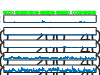

% plot example neural activity

addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 60; %113;
xlimit = [0 400]; %[200 600];
ylimit = [0 80];
% threshold_value = 50; % Define your threshold value here
% force_idx = [1, 3, 12]; % Define your force_idx list

figure

% Create a common x-axis for the top plot
x_common = 0:0.1:(size(acc_neural_activity_data, 1)-1)/10;
% Create the dot plot in the second row
subaxis(example_num+1,1,1, 'Spacing', 0.01, 'Padding', 0.01, 'Margin', 0.03);
plot(force_idx/10, 0, 'go', 'MarkerSize', 1); % Adjust MarkerSize as needed
% xlim([0 (size(acc_neural_activity_data, 1)-1)/10]);
xlim(xlimit);
ylim(ylimit);
axis off; % Remove axis
hold off;

for i = 1:example_num

        % Create the subplots
        subaxis(example_num+1, 1, i+1, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
        neural_activity = acc_neural_activity_data(:, display_start+i);
        b = plot(x_common, neural_activity);
        xlim(xlimit);
        ylim(ylimit);
%     % Change x-axis labels
%     xticks([0 200 400]);
%     xticklabels({'0', '200', '400'});
end

filename = [output_dir Date '_' Animal '_exmple_activity_traces_force.png'];
saveas(gcf, filename);

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2 || norm == 3 || norm == 4
    climit = [-2 2];
else
    climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.5477    0.5857    1.2754    1.3437    1.0559    1.4075    0.8822    1.3933    1.1228    0.1198    0.4356    0.4414   -0.0319   -0.2097   -0.4892   -0.5469   -0.8595   -0.8698   -0.7725   -1.0259   -0.7712   -1.0665   -1.7527   -1.9669   -1.9885   -1.3517   -1.0625   -0.8539   -0.1564    0.2135    0.4841    0.5268    0.4540    0.7375    0.9955    1.1683    1.2487    1.1341    0.8912    1.2055    0.7080    0.8742    1.0614    0.9853    0.2779    0.9220    0.6904    0.4421    0.0197   -0.1185
    0.3694    0.8098    0.7053    0.7411    1.1769    0.9341    0.1826    0.7646    1.2752    1.3627    0.7229    0.8714    1.2177    1.1457    1.3009    1.2397    1.2241    0.6350    0.1172    0.2701    0.4637    0.9026    0.0781   -0.2370   -0.9596   -1.0077   -1.6781   -1.2189   -1.6175   -1.5415   -1.4108   -1.4254   -1.8134   -1.2788   -2.1735   -1.4915   -1.4438   -0.9780   -0.8869   -0.8720   -0.9976   -0.5377   -0.0433    0.1025    0.1171    0.1318    1.3035    0.3231    0.8746 

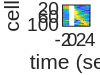

    imagesc(-before_event:0.1:after_event,1:size(trial_start_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
% end

filename = [output_dir Date '_' Animal, '_trial_start_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.9979    1.8035    1.7910    1.2471    0.7204    0.4076    0.3137    0.3271   -0.2932   -0.0247   -0.2680   -0.9966   -0.2372   -0.5564   -1.0182   -0.7790   -0.9246   -1.1168   -1.1543   -1.8718   -1.2748   -1.5671   -0.0962   -0.0890    0.3607    0.4080    0.8786    0.4587    0.9146    1.3670    1.3410    1.1825    1.5404    0.9058    1.3536    1.2538    0.7496    0.4126    0.6888    0.2427    0.4575    0.0218    0.6118    0.6291   -0.2077   -0.3943   -0.1601   -0.4688   -0.6254   -0.9715
    1.3511    1.3624    1.3102    1.3682    1.1452    0.7217    0.8794    1.5549    1.2601    1.0788    0.5467    0.4664   -0.0467    0.1759    0.0768    1.0311    0.8433    0.8947    0.6845    1.1103    0.0458   -0.3826   -0.8438   -1.0116   -1.0187   -0.6021   -0.4754   -0.6593   -1.2272   -1.0282   -0.5760   -1.1541   -1.6544   -1.8989   -1.3445   -1.7681   -1.8902   -1.8186   -1.5772   -0.9354   -0.5721   -0.2268   -0.3589   -0.6014   -1.1000   -0.8803   -0.4879    0.1655   -0.0244 

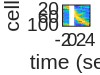

    imagesc(-before_event:0.1:after_event,1:size(trial_end_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;    
% end

filename = [output_dir Date '_' Animal, '_trial_end_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = position_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.6155    1.1287    1.1773    1.0327    1.0133    1.1187    1.2440    0.8290    1.1482    1.1294    0.9417    0.9965    1.1243    0.9736    0.8713    0.6188    0.2252    0.0006   -0.2214   -0.7273   -0.9563   -1.3926   -1.6446   -1.8390   -1.8025   -2.0011   -1.9832   -1.8484   -1.5760   -1.8791   -1.4219   -1.2797   -0.7567   -0.6481   -0.6711   -0.3846   -0.6453   -0.4957   -0.6365   -0.2049    0.0177   -0.2920    0.1119   -0.1314    0.0598    0.3190    0.3893    0.6591    0.6374    0.8230
    1.6415    1.5572    1.0478    0.5786    0.2131   -0.2279   -0.3037   -0.4916   -0.8156   -0.8245   -1.1758   -1.3901   -1.2973   -1.2793   -1.3120   -1.2424   -1.3240   -1.3254   -1.2697   -1.1673   -1.2218   -1.1475   -0.9600   -0.7867   -0.8380   -0.7970   -1.0865   -1.0755   -1.1024   -0.8292   -0.8462   -0.8477   -0.5555   -0.3956   -0.2568   -0.1051    0.2972    0.3788    0.3913    0.5406    0.8678    0.6709    0.9288    1.0920    1.2047    1.2530    1.2358    1.0992    1.0628 

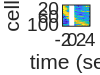

    imagesc(-before_event:0.1:after_event,1:size(position_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
    % end

filename = [output_dir Date '_' Animal, '_position_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     2.1952    2.0426    2.0452    1.5468    1.1089    1.5813    1.2848    1.2306    1.1288    0.5018    0.8456    0.7102    0.1315    0.1411    0.2176   -0.1067    0.3673   -0.0344    0.3939    0.5625   -0.3551   -0.8080   -1.5319   -1.7776   -1.7825   -1.6983   -1.3816   -1.5760   -1.6674   -1.5765   -1.4535   -1.2813   -1.1857   -1.2081   -0.7846   -0.7876   -0.3088   -0.5018   -0.2072   -0.2305   -0.2811   -0.2144    0.0805   -0.3897   -0.0995   -0.0098    0.1654    0.0146   -0.0289   -0.4171
    1.1647    1.6758    1.8692    1.5058    1.7707    1.7808    1.4543    1.2005    0.9566    1.2421    1.3441    1.0273    0.9256    0.8658    0.9424    0.8955    0.5077    0.4705   -0.0458    0.0946   -0.6219   -0.8021   -1.3401   -0.9264   -1.5709   -1.5454   -1.4867   -1.6500   -1.7191   -1.3061   -1.4242   -1.2270   -1.0733   -1.1993   -0.8072   -0.8128   -0.5779   -0.4502   -0.4601   -0.7256   -0.6851   -1.0319   -0.3955   -0.6219   -0.6346    0.1048   -0.0407    0.0047   -0.0899 

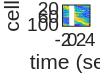

    imagesc(-before_event:0.1:after_event,1:size(force_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
    % end

filename = [output_dir Date '_' Animal, '_force_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.4736    0.8949    1.4038    1.0710    0.7797    0.7474    1.1105    1.3109    1.0476    0.8464    0.5867    0.4557    0.4827    0.6835    0.9910    0.8728    0.9582    0.7439    0.7974    0.2457   -0.3199   -0.8507   -0.9910   -0.9962   -0.9083   -0.6992   -0.6447   -1.3113   -1.3038   -0.7570   -0.9277   -1.6857   -1.9003   -1.6707   -1.7364   -1.7259   -1.8592   -1.5560   -1.1453   -0.7707   -0.2310   -0.5024   -0.3643   -0.9396   -0.9562   -0.2677    0.1779   -0.0074    0.4628    0.8257
    1.0597    0.9043    1.1169    1.1024    1.1149    1.3097    1.1966    1.1409    1.1663    0.8364    0.9593    0.9980    0.8997    1.0821    1.0651    0.6465    0.7383    0.7709    0.7559    0.0416   -0.1043   -0.0759   -0.1448   -0.6142   -0.6529   -1.0270   -1.3107   -1.2703   -1.6326   -1.6443   -1.5711   -1.7712   -1.8849   -1.7017   -1.5805   -1.3415   -1.3508   -1.1952   -0.7219   -0.6117   -0.2967    0.1139    0.3350   -0.0145   -0.7121   -0.6291   -1.1816   -0.7210   -0.5519 

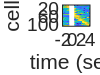

    imagesc(-before_event:0.1:after_event,1:size(reward_act,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)')
    % x=0 に白い縦線を描画
    hold on; % プロットを追加するために hold on を使用
    yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
    plot([0 0], yLimits, 'w-', 'LineWidth', 2); % x=0 に白い縦線を描画
    hold off;
    % end

filename = [output_dir Date '_' Animal, '_reward_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

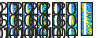

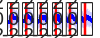

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_actss{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(pull_actss{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;
    end
        
    filename = [output_dir Date '_' Animal, '_pull_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values = mean(pull_actss{i}, 1);
        std_values = std(pull_actss{i}, 0, 1);
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % xlim = [-2,4]
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
         axis tight;
    end
        
        filename = [output_dir Date '_' Animal, '_pull_eta_activity.png'];
        saveas(gcf,filename);
    % close all;
end

% write eta code by categrizing neurons by layers
if categorize == 'layer'
    layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
    layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
    
    startAreas = cat(2,start_I,pointAreas);
    startAreas = sortrows(startAreas);
    startAreas(:,1) = [];
    trial_start_act_layer23_cells = trial_start_act(find(startAreas == 1),:);
    trial_start_act_layer5_cells  = trial_start_act(find(startAreas == 0),:);
    
    endAreas = cat(2,end_I,pointAreas);
    endAreas = sortrows(endAreas);
    endAreas(:,1) = [];
    trial_end_act_layer23_cells = trial_end_act(find(endAreas == 1),:);
    trial_end_act_layer5_cells  = trial_end_act(find(endAreas == 0),:);
    
    posAreas = cat(2,pos_I,pointAreas);
    posAreas = sortrows(posAreas);
    posAreas(:,1) = [];
    position_act_layer23_cells = position_act(find(posAreas == 1),:);
    position_act_layer5_cells  = position_act(find(posAreas == 0),:);
    
    forceAreas = cat(2,force_I,pointAreas);
    forceAreas = sortrows(forceAreas);
    forceAreas(:,1) = [];
    force_act_layer23_cells = force_act(find(forceAreas == 1),:);
    force_act_layer5_cells  = force_act(find(forceAreas == 0),:);
    
    rewardAreas = cat(2,reward_I,pointAreas);
    rewardAreas = sortrows(rewardAreas);
    rewardAreas(:,1) = [];
    reward_act_layer23_cells = reward_act(find(rewardAreas == 1),:);
    reward_act_layer5_cells  = reward_act(find(rewardAreas == 0),:);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if categorize == 'layer' & Kota_alignment == 1
    pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullAreass   = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pullAreas = cat(2,pull_Is(i,:),pointAreas);
        pullAreas = sortrows(pullAreas);
        pullAreas(:,1) = [];
        pull_act_layer23_cells{i} = pull_actss{i}(find(pullAreas == 1),:);
        pull_act_layer5_cells{i}  = pull_actss{i}(find(pullAreas == 0),:);
        pullAreass{i} = pullAreas;
    end
end

次を使用中のエラー: cat
連結する配列の次元が一致しません。

% plot layer23 neural activity
% plot neural activity heatmap
if categorize == 'layer'
    climit = [0 50]
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image = transpose(layer23_cells)
    %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(0:0.1:(size(layer23_cells,1)-1)/10,1:size(layer23_cells,2),image,clims);
    %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    
    filename = [output_dir Date '_' Animal, '_layer23_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

if categorize == 'layer'
    addpath([working_directory 'Utility' filesep 'Subaxis']);
    example_num = 5;
    display_start = 1; %113;
    ylimit=[0 150];
    figure
    for i = 1:example_num
        subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
        b = plot(0:0.1:(size(layer23_cells,1)-1)/10,layer23_cells(:,display_start+i));
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim(ylimit); 
        xlim([0 (size(layer23_cells,1)-1)/10])
    %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end
    filename = [output_dir Date '_'  Animal, '_layer23_exmple_activity_traces.png'];
    saveas(gcf,filename);
end

% plot layer5 neural activity
% plot neural activity heatmap
if categorize == 'layer'
    climit = [0 50]
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image = transpose(layer5_cells)
    %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(0:0.1:(size(layer5_cells,1)-1)/10,1:size(layer5_cells,2),image,clims);
    %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    
    filename = [output_dir Date '_' Animal, '_layer5_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

if categorize == 'layer'
    addpath([working_directory 'Utility' filesep 'Subaxis']);
    example_num = 5;
    display_start = 1; %113;
    ylimit=[0 150];
    figure
    for i = 1:example_num
        subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.05);
        b = plot(0:0.1:(size(layer5_cells,1)-1)/10,layer5_cells(:,display_start+i));
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim(ylimit); 
        xlim([0 (size(layer5_cells,1)-1)/10])
    %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end
    filename = [output_dir Date '_'  Animal, '_layer5_exmple_activity_traces.png'];
    saveas(gcf,filename);
end

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    if norm == 1
        climit = [0 1];
    elseif norm == 2 || norm == 3 || norm == 4
        climit = [-2 2];
    else
        climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells};
    layer5_act  = {trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells};
    title_list = {'Trial start', 'Trial end', 'Position', 'Force', 'Reward'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');

    for i = 1:length(layer23_act) 
        subaxis(1,length(layer23_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer23_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer23_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;        
    end
%     xlabel('time (sec)');
   
    filename = [output_dir Date '_' Animal, '_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer5_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer5_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;        
    end
%     ylabel('cell');
    filename = [output_dir Date '_' Animal, '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if categorize == 'layer' & Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;           
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values = mean(pull_act_layer23_cells{i}, 1);
        std_values = std(pull_act_layer23_cells{i}, 0, 1);
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;        
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
        
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;          
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values = mean(pull_act_layer5_cells{i}, 1);
        std_values = std(pull_act_layer5_cells{i}, 0, 1);
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;          
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        mean_values23 = mean(pull_act_layer23_cells{i}, 1);
        std_values23 = std(pull_act_layer23_cells{i}, 0, 1);        
        mean_values5 = mean(pull_act_layer5_cells{i}, 1);
        std_values5 = std(pull_act_layer5_cells{i}, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        ylim([-2,2]);
        plot([0 0], [-2,2], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画        
        hold off;
        axis tight;          
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir Date '_' Animal, '_pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% Dimention reduction using PCA, tSNE and UMAP
comp_pca = pca(transpose(zscore_rows(transpose(acc_neural_activity_data))));
comp_tsne = tsne(zscore_rows(transpose(acc_neural_activity_data)));

figure
scatter(comp_pca(:,1),comp_pca(:,2));
xlabel('PC1');
ylabel('PC2');

figure
scatter(comp_tsne(:,1),comp_tsne(:,2));
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');

if categorize == 'depth'
    startDepth = cat(2,start_I,depth); %(sig_cell_idxs{1}));
    startDepth = sortrows(startDepth);
    startDepth(:,1) = [];
    
    endDepth = cat(2,end_I,depth);
    endDepth = sortrows(endDepth);
    endDepth(:,1) = [];
    
    posDepth = cat(2,pos_I,depth);
    posDepth = sortrows(posDepth);
    posDepth(:,1) = [];
    
    forceDepth = cat(2,force_I,depth);
    forceDepth = sortrows(forceDepth);
    forceDepth(:,1) = [];
    
    rewardDepth = cat(2,reward_I,depth);
    rewardDepth = sortrows(rewardDepth);
    rewardDepth(:,1) = [];
end

if categorize == 'layer'
    colorcode = pointAreas;
end
if categorize == 'depth'
    colorcode = depth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); % ,depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_tSNE.png'];
saveas(gcf,filename);

% Dimention reduction of trial_start_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_start_act));
comp_tsne = tsne(trial_start_act);
if categorize == 'layer'
    colorcode = startAreas;
end
if categorize == 'depth'
    colorcode = startDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_trial_start_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal,'_' categorize '_trial_start_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_start_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_trial_start_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_start_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_trial_start_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of trial_end_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_end_act));
comp_tsne = tsne(trial_end_act);
if categorize == 'layer'
    colorcode = endAreas;
end
if categorize == 'depth'
    colorcode = endDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_trial_end_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_trial_end_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_end_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_trial_end_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_end_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_trial_end_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of position_act using PCA and tSNE 
comp_pca = pca(transpose(position_act));
comp_tsne = tsne(position_act);
if categorize == 'layer'
    colorcode = posAreas;
end
if categorize == 'depth'
    colorcode = posDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_position_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_position_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,position_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_position_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,position_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_position_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of force_Act using PCA and tSNE 
comp_pca = pca(transpose(force_act));
comp_tsne = tsne(force_act);
if categorize == 'layer'
    colorcode = forceAreas;
end
if categorize == 'depth'
    colorcode = forceDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_force_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_force_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,force_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_force_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,force_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_force_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of reward_Act using PCA and tSNE 
comp_pca = pca(transpose(reward_act));
comp_tsne = tsne(reward_act);
if categorize == 'layer'
    colorcode = rewardAreas;
end
if categorize == 'depth'
    colorcode = rewardDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_reward_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir Date '_'  Animal, '_' categorize '_reward_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,reward_act_max_act_times,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal, '_reward_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,reward_act_max_act_times,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir Date '_'  Animal,'_reward_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Color hidden dimention by depth of cells
if categorize == 'layer'
    autumn = colormap('autumn');
    winter = colormap('winter');
    scaled_autumn_colors = interp1(linspace(1,size(transpose(layer23_cells),2),size(autumn,1)),autumn, 1:size(transpose(layer23_cells),2));
    scaled_winter_colors = interp1(linspace(1,size(transpose(layer5_cells),2),size(winter,1)),winter, 1:size(transpose(layer5_cells),2));
    layer23_comp_pca = pca(zscore_rows(transpose(layer23_cells)));
    layer5_comp_pca = pca(zscore_rows(transpose(layer5_cells)));
    figure
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    xlabel('PC1');
    ylabel('PC2');
    colormap(flipud(colormap));
    filename = [output_dir Date '_'  Animal, '_layer23_PCA_timecourse.png'];
    saveas(gcf,filename);

    figure
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    xlabel('PC1');
    ylabel('PC2');
    colormap(flipud(colormap));
    filename = [output_dir Date '_'  Animal, '_layer5_PCA_timecourse.png'];
    saveas(gcf,filename);
end

% layer specific dimention reduced neural activity timecourse

% layer23_act = [trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells];
% layer5_act  = [trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells];

% Dimention reduction of reward_Act using PCA and tSNE 

% Color hidden dimention by depth of cells
if categorize == 'layer'
    autumn = colormap('autumn');
    winter = colormap('winter');
    scaled_autumn_colors = interp1(linspace(1,size(layer23_act{1},2),size(autumn,1)),autumn, 1:size(layer23_act{1},2));
    scaled_winter_colors = interp1(linspace(1,size(layer23_act{1},2),size(winter,1)),winter, 1:size(layer23_act{1},2));
    figure
    for i = 1:length(layer5_act) 
        layer23_comp_pca = pca(layer23_act{i});
        layer5_comp_pca = pca(layer5_act{i});
        subaxis(length(layer5_act),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
        scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
        title(title_list{i});
        ylabel('PC2');
        if i == 5
            xlabel('PC1');
        end
        subaxis(length(layer5_act),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
        title(title_list{i});
        colormap(flipud(colormap));
        % colorbar('Direction','reverse');
        % caxis([0 1100]);
    end
    xlabel('PC1');
    filename = [output_dir Date '_'  Animal, '_' categorize '_eta_PCA_timecourse.png'];
    saveas(gcf,filename);
end

if categorize == 'layer'
    figure
    for i = 1:length(layer5_act) 
        layer23_comp_tsne = tsne(transpose(layer23_act{i}));
        layer5_comp_tsne = tsne(transpose(layer5_act{i}));
        subaxis(length(layer5_act),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
        scatter(layer23_comp_tsne(:,1),layer23_comp_tsne(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
        title(title_list{i});
        ylabel('t-SNE coordinate2');
        if i == 5
            xlabel('t-SNE coordinate1');
        end
        subaxis(length(layer5_act),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
        scatter(layer5_comp_tsne(:,1),layer5_comp_tsne(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
        title(title_list{i});
    %     xlabel('t-SNE coordinate1');
    %     ylabel('t-SNE coordinate2');
        colormap(flipud(colormap));
    %     colorbar('Direction','reverse');
    %     caxis([0 1100]);
    end
    xlabel('t-SNE coordinate1');
    filename = [output_dir Date '_'  Animal, '_' categorize '_eta_tSNE_timecourse.png'];
    saveas(gcf,filename);
end

% split trials and eta anlysis for detecting prediction error or action
% value
trial        = behavior_neural_time(:,2);
resistance   = behavior_neural_time(:,5);
res_all  = unique(sort(resistance));
res_high = res_all(2);
res_low  = res_all(1);
switch_inter = NaN;
if contains(Key,'heavy')
    session_type = res_high;
elseif contains(Key,'light')
    session_type = res_low;
elseif contains(Key,'roving')
    Keynum = regexp(Key,'\d+','match')
    if length(Keynum)>0
        switch_inter = str2num(Keynum{1});
    end
end
% trial_end and do not get reward (reward prediction error)
% no_reward_idx  = find(trial_end == 1);
no_reward_idx = [];
for i = 1:length(trial_end_idx)
    if any(reward_idx >= i & reward_idx < i+fps)% there is reward_idx == j
        continue;% skip for loop
    end
    no_reward_idx(end+1) = trial_end_idx(i); % no reward within 1 seconds
%     if trial_end_idx(i) reward_idx % no reward within 1 seconds
%         no_reward_idx(end+1) = trial_end_idx(i)
%     end
end
% force during trial in which session type == trial type
% force during trial in which session type != trial type (sensory prediction error)
prediction_error_idx    = [];
prediction_no_error_idx = [];
for i = 1:length(force_idx)
    if force_idx(i)+fps < length(trial)
        temp_resistance = min(resistance(force_idx(i):force_idx(i)+fps)); % expand 1 sec to include force just before trial
    else    
        temp_resistance = resistance(force_idx(i));
    end
    if ~isnan(switch_inter)
        if rem((i-1),(switch_inter*2)) <= switch_inter
            session_type = res_low;
        else
            session_type = res_high;
        end
    end

    if temp_resistance == Inf
        continue; % skip for loop
    % case of roving oddball paradigm
    elseif length(Keynum) == 0
        pre_trial_idx = max(trial_end_idx(trial_end_idx<force_idx(i)))-1;
        post_trial_idx = min(trial_start_idx(trial_start_idx>force_idx(i)))+1;
        pre_trial_resistance = resistance(pre_trial_idx);
        post_trial_resistance = resistance(post_trial_idx);
        if temp_resistance ~= pre_trial_resistance
            prediction_error_idx(end+1) = force_idx(i);
        elseif temp_resistance ~= post_trial_resistance
            prediction_no_error_idx(end+1) = force_idx(i);
        end
    elseif temp_resistance ~= session_type
        prediction_error_idx(end+1) = force_idx(i);
    elseif temp_resistance == session_type
        prediction_no_error_idx(end+1) = force_idx(i);
    end
end
% action value can only calculated in session in which reward amount is
% changed
% force during trial in which reward is high (Q:action value)
% force during trial in which reward is low
action_value_idx    = [];
action_no_value_idx = [];
for i = 1:length(force_idx)
    if force_idx(i)+fps < length(trial)
        temp_trial      = max(trial(force_idx(i):force_idx(i)+fps));
        temp_resistance = min(resistance(force_idx(i):force_idx(i)+fps)); % expand 1 sec to include force just before trial
    else
        temp_trial      = trial(force_idx(i));
        temp_resistance = resistance(force_idx(i));
    end
    if temp_resistance == Inf
        continue; % skip for loop
    elseif temp_trial <= totalTrial/2 && temp_resistance == res_high
        action_no_value_idx(end+1) = force_idx(i);
    elseif temp_trial <= totalTrial/2 && temp_resistance == res_low
        action_value_idx(end+1)    = force_idx(i);
    elseif temp_trial > totalTrial/2 && temp_resistance == res_high
        action_value_idx(end+1)    = force_idx(i);
    elseif temp_trial > totalTrial/2 && temp_resistance == res_low
        action_no_value_idx(end+1) = force_idx(i);
    end
end

eta_acts = cell(1,6);
eta_actss = cell(1,6);
eta_idxs = {no_reward_idx, reward_idx, prediction_error_idx, prediction_no_error_idx, action_value_idx, action_no_value_idx}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
% eta_idxs = {reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_no_value_idx, action_value_idx}; %{reward_idx, no_reward_idx, prediction_no_error_idx, prediction_error_idx, action_value_idx, action_no_value_idx};
eta_idx_idxs = [2,1,4,3,5,6];
max_acts = cell(1,6);
sig_cell_idxs2 = cell(1,6);
max_I = cell(1,6);
max_act_times = cell(1,6);

for i = 1:length(eta_acts)
    eta_acts{i} = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
    exception_count = 0;
    i_eta_acts = {};
    for j = 1:length(eta_idxs{i})
        if eta_idxs{i}(j)-fps*before_event<=0 | eta_idxs{i}(j)+fps*after_event>size(acc_neural_activity_data,1)
            exception_count = exception_count + 1;
        else
            eta_acts{i} = eta_acts{i}+transpose(acc_neural_activity_data(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
            i_eta_acts{end+1}= transpose(acc_neural_activity_data(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
        end
    end
    eta_acts{i} = eta_acts{i}/(length(eta_idxs{i})-exception_count);
    i_eta_acts = reshape(cell2mat(i_eta_acts),[size(acc_neural_activity_data, 2) size(eta_acts{i},2) length(eta_idxs{i})-exception_count]); %-1]);
    eta_actss{i} = i_eta_acts;
    if norm == 1
        eta_acts{i} = normalize_rows(eta_acts{i});
    elseif norm ==2
        eta_acts{i} = zscore_rows(eta_acts{i}); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
        for i_cell = 1:size(acc_neural_activity_data, 2)
            [~,max_idx] = max(mean(i_eta_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_acts{i} = i_eta_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal'); %temporal,'Alpha',0.001
%             [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal','Alpha',0.001); %temporal,'Alpha',0.001
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs2{i} = sig_cell_idx;
        end
        eta_acts{i} = zscore_rows(eta_acts{i}(find(sig_cell_idx==1),:));
    elseif norm == 4 % zscored no error activity by error or action value activity
        if i == 2 || i == 4 || i == 6
            eta_acts{i} = zscore_rows_by_diff_matrix(eta_acts{i},eta_old);
        else
            eta_old = eta_acts{i};
            eta_acts{i} = zscore_rows(eta_acts{i}); 
        end
    end
    [M,max_I{i}] = max(eta_acts{i},[],2);
    eta_acts{i} = cat(2,max_I{i},eta_acts{i});
    eta_acts{i} = sortrows(eta_acts{i});
    max_act_times{i} = eta_acts{i}(:,1)/10 -2;
    eta_acts{i}(:,1) = [];
end
eta_acts = eta_acts(eta_idx_idxs);
max_acts = max_acts(eta_idx_idxs);
max_I = max_I(eta_idx_idxs);
max_act_times = max_act_times(eta_idx_idxs);

% % check the number of action value represented cells
% sig_cell_idxs{4}; % force_idx
% sig_cell_idxs2{5}; % action_value_idx
% sig_cell_idxs2{6}; % action_no_value_idx
% all_set = sum(sig_cell_idxs{4}==1)
% and_set = sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3)
% value_set = sum(sig_cell_idxs{4}+sig_cell_idxs2{5}==2) - sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3)
% no_value_set = sum(sig_cell_idxs{4}+sig_cell_idxs2{6}==2) - sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3)
% rem_set = sum(sig_cell_idxs{4}==1) + sum(sig_cell_idxs{4}+sig_cell_idxs2{5}+sig_cell_idxs2{6}==3) - sum(sig_cell_idxs{4}+sig_cell_idxs2{5}==2) - sum(sig_cell_idxs{4}+sig_cell_idxs2{6}==2)
% action_value_cell_num = [all_set and_set value_set no_value_set rem_set];
% 
% filename = [output_dir Date '_' Animal '_action_value_cell.csv'];
% writematrix(action_value_cell_num,filename);

% write eta code by categrizing neurons by layers
eta_layer23_acts = cell(1,6);
eta_layer5_acts  = cell(1,6);
etaAreas         = cell(1,6);

if categorize == 'layer'  
    for i = 1:length(eta_acts)
        etaAreas{i} = cat(2,max_I{i},pointAreas);
        etaAreas{i} = sortrows(etaAreas{i});
        etaAreas{i}(:,1) = [];
        eta_layer23_acts{i} = eta_acts{i}(find(etaAreas{i} == 1),:);
        eta_layer5_acts{i}  = eta_acts{i}(find(etaAreas{i} == 0),:);
    end
end

% plot neural activity heatmap
title_list = {'Reward', 'Reward miss', 'Force usual resistance', 'Force rare resistance', 'Force high reward', 'Force low reward'};
if norm == 1
    climit = [0 1];
elseif norm == 2 || norm == 3 || norm == 4
    climit = [-2 2];
else
    climit = [0 20]; %[0 50];
end

for i = 1:length(eta_acts)
    figure
    set(gcf,'color','w');
    % for i = 1:length(brain_roi) 
    %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        clims = climit;
        image = eta_acts{i} %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(eta_acts{i},1),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    % end
    
    filename = [output_dir Date '_' Animal '_' title_list{i} '_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;
end

figure
set(gcf,'color','w');

for i = 1:length(eta_acts) 
    subaxis(1,length(eta_acts),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
    clims = climit;
    image = eta_acts{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(-before_event:0.1:after_event,1:size(eta_acts{i},1),image,clims);
%         ylabel('cell');
    xlabel('time (sec)');
    if i == 1
        ylabel('cell');
    end
    title(title_list{i});
end
%     xlabel('time (sec)');

filename = [output_dir Date '_' Animal '_' strrep(strjoin(title_list),' ','_') '_eta_activity_heatmap.png'];
saveas(gcf,filename);

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    figure
    set(gcf,'color','w');
    for i = 1:length(eta_layer23_acts) 
        subaxis(1,length(eta_layer23_acts),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = eta_layer23_acts{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(eta_layer23_acts{i},1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    filename = [output_dir Date '_' Animal '_' strrep(strjoin(title_list),' ','_') '_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure
    set(gcf,'color','w');
    for i = 1:length(eta_layer5_acts) 
        subaxis(1,length(eta_layer5_acts),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = eta_layer5_acts{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(eta_layer5_acts{i},1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    filename = [output_dir Date '_' Animal '_' strrep(strjoin(title_list),' ','_')  '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

% plot example neural activity
high_low_reward_idx = sig_cell_idxs2{5} & sig_cell_idxs2{6};
high_reward_idx     = sig_cell_idxs2{5} & ~sig_cell_idxs2{6};
low_reward_idx      = ~sig_cell_idxs2{5} & sig_cell_idxs2{6};
neither_idx         = ~sig_cell_idxs2{5} & ~sig_cell_idxs2{6};
example_num = 4;
categories   = {high_low_reward_idx, high_reward_idx, low_reward_idx, neither_idx};
category_str = {'high_and_low_reward','high_reward','low_reward','neither_reward'};

Force_act = mean(force_acts,3);
Force_act_high = mean(eta_actss{5},3);
Force_act_low = mean(eta_actss{6},3);

for m = 1:length(categories)
    figure
    m_category = categories{m};
    all_cell = find(m_category == 1);
    for i = 4:7 %1:example_num
        i_cell = all_cell(i);

        Force_act = squeeze(force_acts(i_cell,:,:));
        Force_act_high = squeeze(eta_actss{5}(i_cell,:,:));
        Force_act_low  = squeeze(eta_actss{6}(i_cell,:,:));
        Force_act_SEM = transpose(std(Force_act,0,2)/sqrt(size(Force_act,2)));
        Force_act_high_SEM = transpose(std(Force_act_high,0,2)/sqrt(size(Force_act_high,2)));
        Force_act_low_SEM  = transpose(std(Force_act_low,0,2)/sqrt(size(Force_act_low,2)));        
        Force_act = transpose(mean(Force_act,2));
        Force_act_high = transpose(mean(Force_act_high,2));
        Force_act_low  = transpose(mean(Force_act_low,2));        
    
        subaxis(example_num,1,i-3, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:0.1:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x,Force_act,'m','LineWidth',2);
        plot(x,Force_act_high,'c','LineWidth',2);
        plot(x,Force_act_low,'g','LineWidth',2);        
        alpha_value = 0.2;
        inBetween1 = [Force_act + Force_act_SEM, fliplr(Force_act - Force_act_SEM)];
        fill(x2, inBetween1, 'm', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween2 = [Force_act_high + Force_act_high_SEM, fliplr(Force_act_high - Force_act_high_SEM)];
        fill(x2, inBetween2, 'c', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween3 = [Force_act_low + Force_act_low_SEM, fliplr(Force_act_low - Force_act_low_SEM)];
        fill(x2, inBetween3, 'g', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);        
        xline(0,'--k');
%         xline(p_time_temp_transformed(find(p_trial_end==1)),'--k');
%         title(['Force eta']);
    %         title(['R2 = ' num2str(R2)]);
        hold off;
        if i_cell ~= example_num
            set(gca,'TickLength',[0 0]);
            set(gca,'XTickLabel',[]);
        end
        if i == 4 %1
            legend({'All','High reward','Low reward'},'Location','northwest');
        end
    end
    xlabel('time');
    filename = [output_dir Date '_'  Animal '_' category_str{m} '_force_ETA.png'];
    saveas(gcf,filename);
end

% plot pie graph
data = [sum(high_low_reward_idx) sum(high_reward_idx) sum(low_reward_idx) sum(neither_idx)];
labels = {'high and low reward','high reward','low reward', 'neither'};
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
p = pie(data); %, labels);
% title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
pText = findobj(p,'Type','text');
percentValues = get(pText,'String');
txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
combinedtxt = strcat(percentValues,txt);
pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
legend(labels,'Location','southoutside'); 

filename = [output_dir Date '_'  Animal, '_' categorize '_action_value_cells_pie.png'];
saveas(gcf,filename);

% % plot pie graph
data = [73 48 17 176];
labels = {'high and low reward','high reward','low reward', 'neither'};
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
p = pie(data); %, labels);
% title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
pText = findobj(p,'Type','text');
percentValues = get(pText,'String');
txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
combinedtxt = strcat(percentValues,txt);
pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
legend(labels,'Location','southoutside'); 

% filename = [output_dir Date '_'  Animal, '_' categorize '_action_value_cells_pie.png'];
% saveas(gcf,filename);

% % Clustering neural activity
% [idx,C] = kmeans(transpose(acc_neural_property_data),3);
% x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
% x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)];
% idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');
% 
% figure;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% colormap(flipud(colormap));
% colorbar('Direction','reverse');
% caxis([0 1100]);
% hold off;

% Example usage
% points = [1, 2; 3, 4; 5, 6]; % Nx2 array of points to classify
% linePoints = [0, 0; 2, 2; 3, 1]; % 3x2 array of points defining the first line
% 
% pointAreas = classifyPoints(points, linePoints);
% disp(pointAreas);

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function zscored_matrix2 = zscore_rows_by_diff_matrix(matrix1, matrix2)
    zscored_matrix2 = (matrix1 - mean(matrix2, 2)) ./ std(matrix2,0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (low:0 or high:1)

    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end